%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:\data\kwave\config\t_pos_2board.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\kgrid.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\sourse_wave.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\rfdata.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\medium.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\kgrid.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\sourse_wave.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = [0,2,4,6,8,10,12,14];
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
reference_point = zeros(num_echo_receiver,num_depth,length(rate_IMCL));
reference_point_lowerlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(num_echo_receiver,num_depth,length(rate_IMCL));%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
focal_signal_total = zeros(length(rate_IMCL),num_depth);
focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_total = zeros(length(rate_IMCL),num_depth);
focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));
focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver,num_depth,length(rate_IMCL));

for kk = 1:length(rate_IMCL)
    v_reference(1,kk) = v_muscle*(1-rate_IMCL(kk)/100) + v_fat*(rate_IMCL(kk)/100);
    for ii = 1:num_depth
        focal_depth(1,ii) = (ii+3)*kgrid.dx;
        focal_point = [0;t_pos(2,1)-focal_depth(1,ii)];
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point);
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(jj,ii,kk) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
            reference_point_upperlimit(jj,ii,kk) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:,ii,kk) = focused_rfdata(1:read_range_rfdata,:,ii,kk)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        hilb_rfdata = hilbert(focused_rfdata(:,:,ii,kk));
        focused_rfdata_amp(:,:,ii,kk) = abs(hilb_rfdata);
        %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
        focused_rfdata_amp_masked(:,:,ii,kk) = focused_rfdata_amp(:,:,ii,kk);
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_amp_masked(1:reference_point_lowerlimit(jj,ii),jj,ii,kk) = 0;
            focused_rfdata_amp_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_lowerlimit(jj,ii):end,jj,ii,kk) = 0;
            focused_rfdata_masked(reference_point_upperlimit(jj,ii):end,jj,ii,kk) = 0;
        end
        [~,point_maxAmp_in_mask(:,ii,kk)] = max(focused_rfdata_amp_masked(:,:,ii,kk),[],1);
        for jj = 1:length(target_element)
            %受信ビームフォーミング（整相加算のため）
            focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                focused_rfdata(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            focal_amp(kk,ii,target_element(jj)) = ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii,kk)/length(target_element);
            %均質性評価指標
            homogeneity_percel(kk,ii,jj) = abs(point_maxAmp_in_mask(jj,ii,kk) - reference_point(jj,ii));
        end
        homogeneity_total(kk,ii) = sum(homogeneity_percel(kk,ii,:))/length(target_element);
    end
end

## 結果を考察するための動画を作成

IMCL: 4 %のときで考える．包絡線の最大値focused_rfdata_amp_maskedを表示．

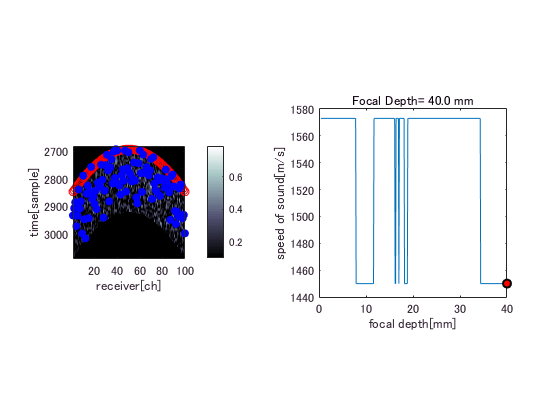

clear mov;
fr(1:num_depth) = struct('cdata',[],'colormap',[]);
target_element = 0;
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1);
for ii = 1:num_depth
    figure(1)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_amp_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    %     colorbar;
    %     h_bar = colorbar;
    %     h_bar.Location = 'west';
    %     a1.Position(3:4) = [0.7750 0.3412];
    %     h_bar.Position(1) = 0.94;
    caxis([0.1 max(max(focused_rfdata_amp_masked(:,:,ii)))]);
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    pause(0.05);
    drawnow;
    fr(ii) = getframe(gcf);
end

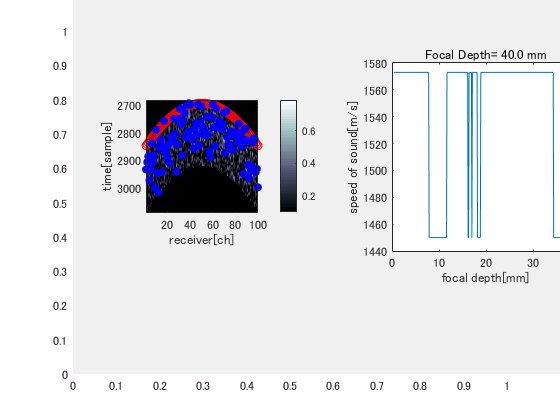

% play movie
figure;
movie(fr)

% save movie
cd('H:/result/2018_10_21_search_path_contain_only_IMCL')
mv = VideoWriter('search_path_contain_only_IMCL_IMCL4%_noclorbar','MPEG-4');
mv.FrameRate = 3; % ← fpsと同じ %ART:3
% mv.Quality = 100;
open(mv)
writeVideo(mv,fr)
close(mv)

IMCL: 4 %のときで考える．RF信号のfocused_rfdata_maskedを表示．マーカーは包絡線の最大値の位置のまま．

インデックスが行列の次元を超えています。

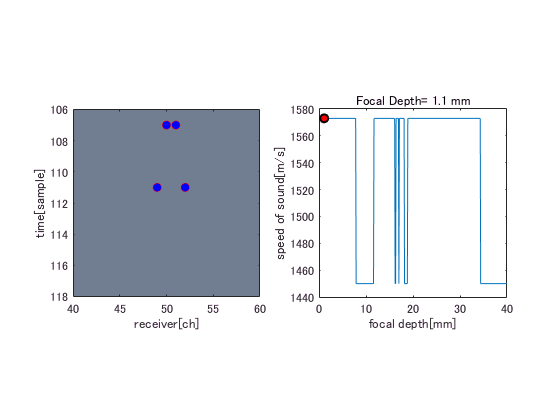

clear mv;
clear fr;
fr(num_depth*3) = struct('cdata',[],'colormap',[]);
target_element = 0;
k = find(abs(gradient(medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))),1);
for ii = 1:num_depth
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,3))) max(max(focused_rfdata_masked(:,:,ii,3)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,3))) max(max(focused_rfdata_masked(:,:,ii,3)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii-1) = getframe(gcf);
        fr(3*ii-2) = getframe(gcf);
    figure(2)
    subplot(1,2,1);
    target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
    imagesc(focused_rfdata_masked(:,:,ii,3));
    hold on
    scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element),ii,3),'red');
    scatter(min(target_element):max(target_element),point_maxAmp_in_mask(min(target_element):max(target_element),ii,3),'blue','filled');
    hold off
    xlabel('receiver[ch]');
    ylabel('time[sample]');
    axis square;
    axis tight;
    if ii<=30
        xlim([40 60])
    else
        xlim([min(target_element) max(target_element)])
    end
    ylim([reference_point_lowerlimit(50,ii,3) reference_point_upperlimit(min(target_element),ii,3)])
    colormap(bone);
    caxis([min(min(focused_rfdata_masked(:,:,ii,3))) max(max(focused_rfdata_masked(:,:,ii,3)))])
    subplot(1,2,2);
    plot(focal_depth*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4):-1:51))
    xlabel('focal depth[mm]');
    ylabel('speed of sound[m/s]');
    hold on
    if ii == k
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),'diamond',...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','yellow',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title({titlename;'(Boundary)'},'Color','red');
    else
        scatter(focal_depth(ii)*1e3,medium.sound_speed(251,round(451-focal_depth(1,1)*1e4)-ii+1),...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor','red',...
            'LineWidth',1.5);
        hold off
        axis square;
        titlename = sprintf('Focal Depth= %0.1f mm',focal_depth(ii)*1e3);
        title(titlename);
    end
    drawnow
    fr(3*ii) = getframe(gcf);
end

% play movie
% figure;
% movie(fr)
% save movie
cd('H:/result/2018_10_21_search_path_contain_only_IMCL')
mv = VideoWriter('search_path_contain_only_IMCL_IMCL4%_noclorbar_rfsignal','MPEG-4');
mv.FrameRate = 9; % ← fpsと同じ %ART:3
% mv.Quality = 100;
open(mv)
writeVideo(mv,fr)
close(mv)